# Test out single-cell simulations with 99% inhibition

I simulated the growth rates and fluxes for 20 cells.

First, let's load the data. Note that in this case I did the following:

- 99% inhibition

- Removed upregulated reactions or genes from KO

Thus, the dataset will have different numbers of reactions and gene knockouts. To do a fast comparison, I'll do a manual comparison and also visualize the growth rate and flux standard deviation for each cell to assess variation.

Let's first do a manual inspection of the data.

clear all
% pick 3 random datapoints.
load D:/Chandrasekaran/Projects/EMT/Analysis/i99/1.mat
random_select_day3_0 = cobra_cell;

load D:/Chandrasekaran/Projects/EMT/Analysis/i99/17.mat
random_select_day3_12 = cobra_cell;

load D:/Chandrasekaran/Projects/EMT/Analysis/i99/8.mat
random_select_day1_0 = cobra_cell;

We'll look at the distributions. There is variation in gene KOs (although most of the action takes place in the third and fourth decimal place).

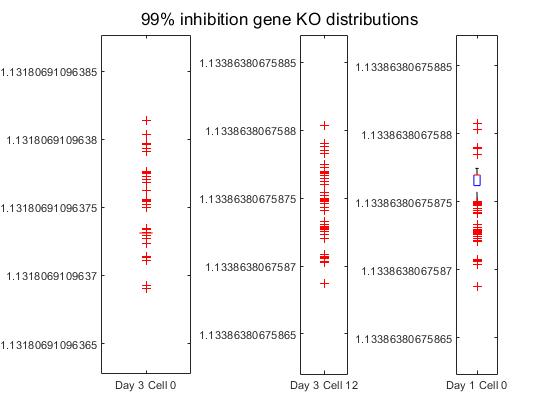

figure;
sgtitle('99% inhibition gene KO distributions');

subplot(1,3,1)
boxplot(random_select_day3_0.geneko)
xticklabels('Day 3 Cell 0')

subplot(1,3,2)
boxplot(random_select_day3_12.geneko)
xticklabels('Day 3 Cell 12')

subplot(1,3,3)
boxplot(random_select_day1_0.geneko)
xticklabels('Day 1 Cell 0')

It is much more difficult to access reaction knockout variation across cells.

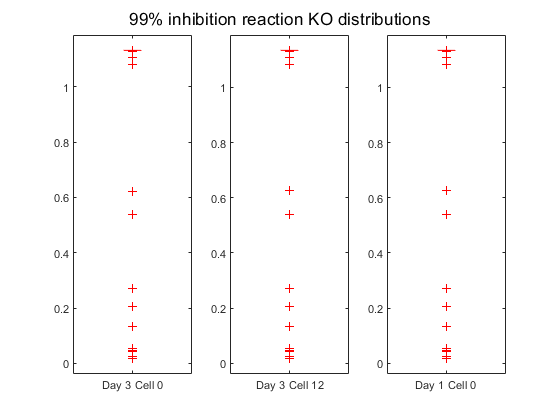

figure;
sgtitle('99% inhibition reaction KO distributions');

subplot(1,3,1)
boxplot(random_select_day3_0.rxnko)
xticklabels('Day 3 Cell 0')

subplot(1,3,2)
boxplot(random_select_day3_12.rxnko)
xticklabels('Day 3 Cell 12')

subplot(1,3,3)
boxplot(random_select_day1_0.rxnko)
xticklabels('Day 1 Cell 0')

And the same goes for metabolic fluxes.

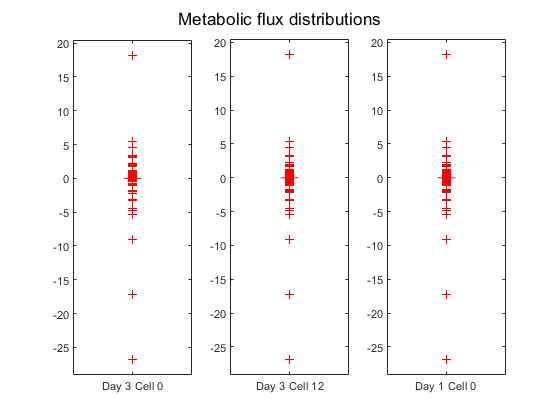

figure;
sgtitle('Metabolic flux distributions');

subplot(1,3,1)
boxplot(random_select_day3_0.flux.x(1:3744))
xticklabels('Day 3 Cell 0')

subplot(1,3,2)
boxplot(random_select_day3_12.flux.x(1:3744))
xticklabels('Day 3 Cell 12')

subplot(1,3,3)
boxplot(random_select_day1_0.flux.x(1:3744))
xticklabels('Day 1 Cell 0')

I simulated 20 cells. Let's visualize the within-cell variation for each experiment.

% MAGIC SIMULATION PATH
path = 'D:/Chandrasekaran/Projects/EMT/Analysis/i99/';

num_of_files =  size(dir([path, '/*.mat']), 1);

mean_flux_val   = zeros([1, num_of_files]);
std_flux_val    = zeros([1, num_of_files]);
mean_geneko_val = zeros([1, num_of_files]);
std_geneko_val  = zeros([1, num_of_files]);
mean_rxnko_val  = zeros([1, num_of_files]);
std_rxnko_val   = zeros([1, num_of_files]);
timepoint       = strings([1, num_of_files]);

special_cases = ["x3d", "x1d", "x7d", "x8h", "x0d"];

for i = 1:num_of_files
    load(sprintf('D:/Chandrasekaran/Projects/EMT/Analysis/i99/%d.mat', i))
    
    if ismember(cobra_cell.id, special_cases)
        new_id = erase(cobra_cell.id, 'x');
    else
        new_id = erase(cobra_cell.id, 'x');
        new_id = split(new_id, '_');
        new_id = string(new_id{1});
    end
    
    mean_flux_val(1, i)   = mean(cobra_cell.flux.x(1:3744));
    std_flux_val(1, i)    = std(cobra_cell.flux.x(1:3744));
    mean_geneko_val(1, i) = mean(cobra_cell.geneko);
    std_geneko_val(1, i)  = std(cobra_cell.geneko);
    mean_rxnko_val(1, i)  = mean(cobra_cell.rxnko);
    std_rxnko_val(1, i)   = std(cobra_cell.rxnko);
    timepoint(1, i)       = new_id;
end

Visualize mean values with barplots

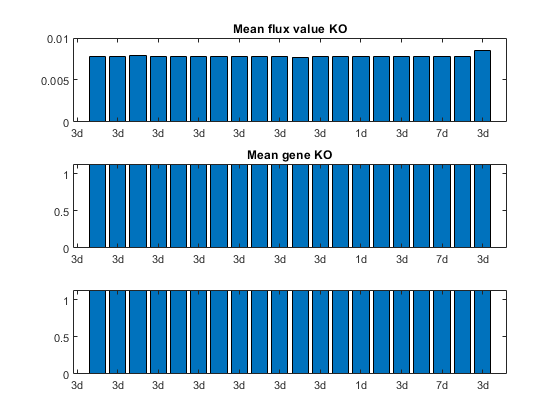

figure;

subplot(3, 1, 1)
bar(abs(mean_flux_val))
title('Mean flux value KO')
xticklabels(timepoint)

subplot(3, 1, 2)
bar(abs(mean_geneko_val))
title('Mean gene KO')
xticklabels(timepoint)

subplot(3, 1, 3)
title('Mean reaction KO')
bar(abs(mean_rxnko_val))
xticklabels(timepoint)

I'll also visualize the values as a table.

table(timepoint', mean_flux_val', mean_geneko_val', mean_rxnko_val', ...
      'VariableNames', {'Time', 'MeanFlux', 'MeanGeneKO', 'MeanRxnKO'})

ans = 20×4 table
    Time     MeanFlux     MeanGeneKO    MeanRxnKO
    ____    __________    __________    _________

    "3d"    -0.0077624      1.1318        1.129  
    "3d"    -0.0078314      1.1339        1.131  
    "3d"    -0.0079216      1.1339        1.131  
    "3d"    -0.0078314      1.1339        1.131  
    "3d"    -0.0077624      1.1318        1.129  
    "3d"    -0.0077624      1.1318        1.129  
    "3d"    -0.0078314      1.1339        1.131  
    "1d"    -0.0078314      1.1339        1.131  
    "3d"    -0.0078314      1.1339        1.131  
    "7d"    -0.0078314      1.1339        1.131  
    "3d"    -0.0077294      1.1318        1.129  
    "3d"    -0.0078314      1.1339        1.131  
    "3d"    -0.0078314      1.1339        1.131  
    "7d"    -0.0078055      1.1339        1.131  
    "3d"    -0.0077624      1.1318        1.12

Visualize standard deviation values with barplots

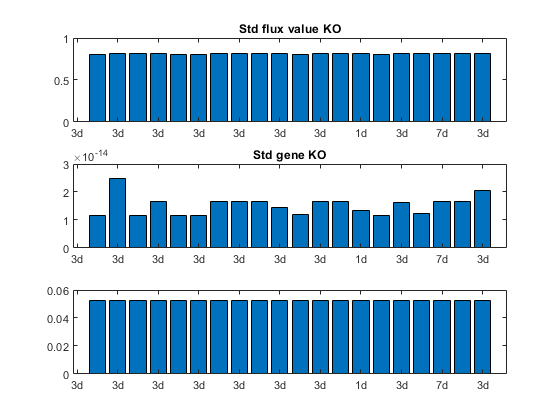

figure;

subplot(3, 1, 1)
bar(std_flux_val)
title('Std flux value KO')
xticklabels(timepoint)

subplot(3, 1, 2)
bar(std_geneko_val)
title('Std gene KO')
xticklabels(timepoint)

subplot(3, 1, 3)
title('Std reaction KO')
bar(std_rxnko_val)
xticklabels(timepoint)

I'll also visualize the values as a table.

table(timepoint', std_flux_val', std_geneko_val', std_rxnko_val', ...
      'VariableNames', {'Time', 'StdFlux', 'StdGeneKO', 'StdRxnKO'})

ans = 20×4 table
    Time    StdFlux    StdGeneKO     StdRxnKO
    ____    _______    __________    ________

    "3d"     0.8081    1.1706e-14    0.052149
    "3d"    0.80953    2.4987e-14    0.052241
    "3d"    0.80964    1.1564e-14    0.052298
    "3d"    0.80953    1.6684e-14    0.052241
    "3d"     0.8081    1.1706e-14    0.052149
    "3d"     0.8081    1.1739e-14    0.052149
    "3d"    0.80953    1.6684e-14    0.052241
    "1d"    0.80953    1.6689e-14    0.052241
    "3d"    0.80953    1.6684e-14    0.052241
    "7d"    0.80953    1.4612e-14    0.052241
    "3d"    0.80848     1.183e-14    0.052149
    "3d"    0.80953    1.6684e-14    0.052241
    "3d"    0.80953    1.6684e-14    0.052241
    "7d"    0.80984    1.3501e-14    0.052255
    "3d"     0.8081    1.1739e-14    0.052149
    "1d"    0.80953    1.6208e-14    0.052241
